# DC_LAB3_AngularVelocity

addpath("plot\");
addpath("Linearization\");
addpath("Modeling\");

## 1. Figure out Steady State 

### 1) Rising time 2.5[sec]

% plot_sweep('../data/Static/Static_0.1.out');
% plot_sweep('../data/Static/Static_0.02.out');
Get_fitting_Quadratic('../data/Static/Static.out');

Positive region: W = -352.6103*V^2 + 3291.1271*V + -6349.4401
Negative region: W = 358.8108*V^2 + -260.8434*V + -1276.6088


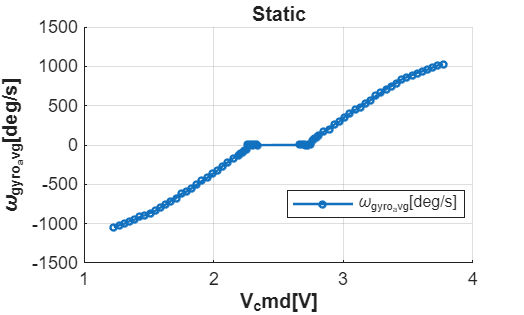

% 
% 
% plot_sweep('../data/Static_Linear/Static.out');


plot_file('../data/Static/Static.out', 1, 2);

Positive region: W = -352.6103*V^2 + 3291.1271*V + -6349.4401
Negative region: W = 358.8108*V^2 + -260.8434*V + -1276.6088


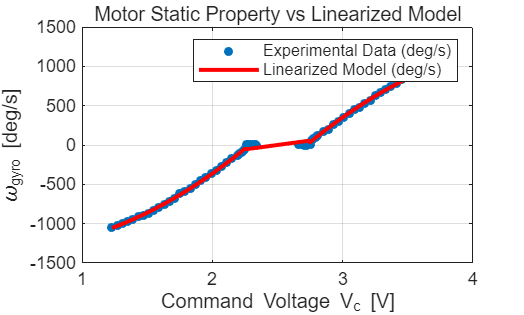

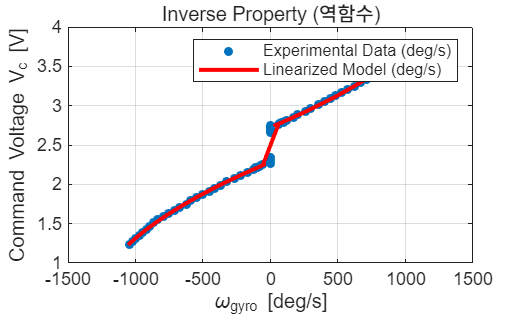

Linear_mapping('../data/Static/Static.out');  

## 2. Obtain Static Motor Property

### 1) Dead-zone at 2.3[V] -> 2.7[V] voltage

### 2) Saturation of Wgyro to 25 [rad/ses] (219 rpm)  (3.66 Hz)

### 3) Linear region positive from 2.7[V] to 3.5[V], negative from 2.3[V] to 1.5[V]

% plot_Wgyro('Slewrate');
% 
% find_coff(0.05, 0.2302, 1.842, 2.72, 2.85, 4.80);
% find_coff(-0.05,-0.2436,-1.7824,2.28,2.15,0.3);


## 3. Validation - triangle

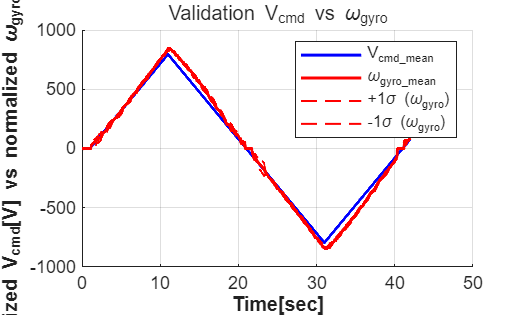

Vali_plot('tri');

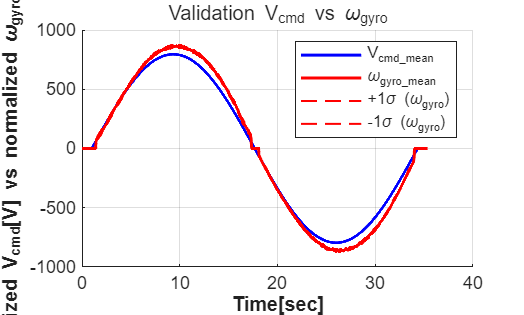

Vali_plot('sin');

%From now on, the path is unified: 
path = '..\data\BodeMag\';

## 4. Bode 

generate_bode_plot(path); 

## 5-1. Obtain Transfer Function  

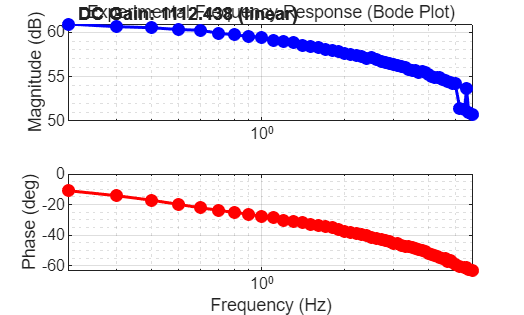

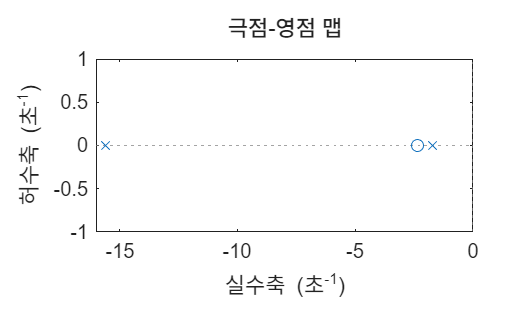


Extracted Physical DC Gain (g_initial):
  Linear Scale: 1112.4385

--- Identified Transfer Function ---
 
num/den = 
 
      13.5271 s + 32.0799
   -------------------------
   s^2 + 17.3293 s + 27.0038


Trans_func(path);

## 5-2. Validation

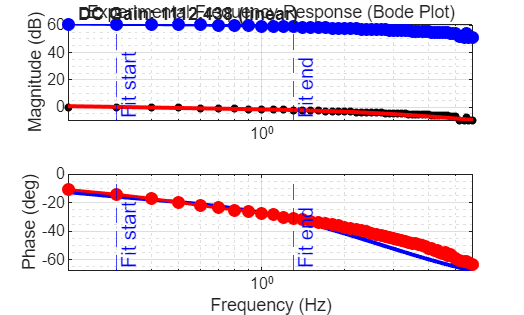


Extracted Physical DC Gain (g_initial):
  Linear Scale: 1112.4385

--- Identified Transfer Function ---
 
num/den = 
 
      13.5271 s + 32.0799
   -------------------------
   s^2 + 17.3293 s + 27.0038


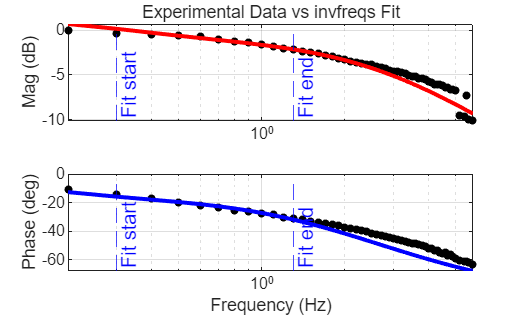

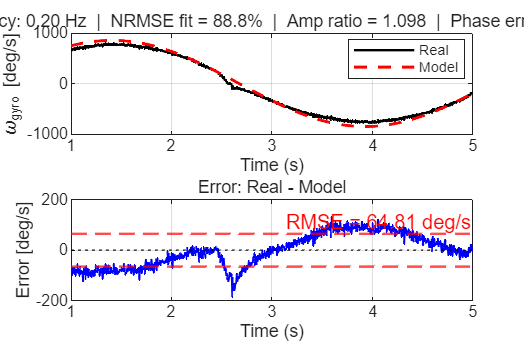

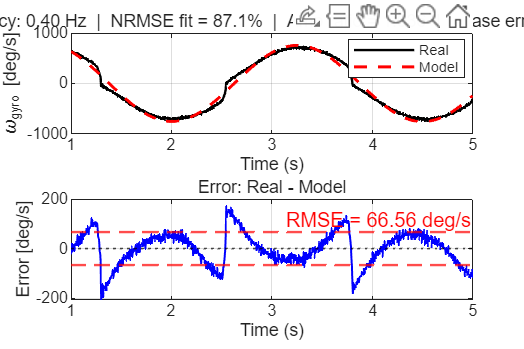

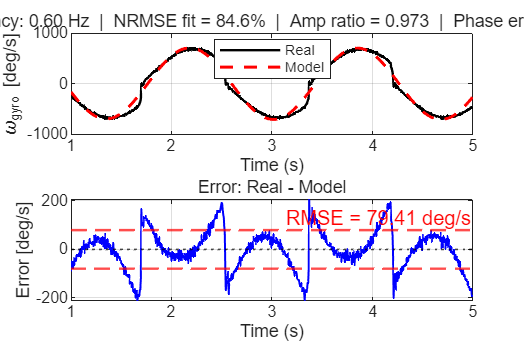

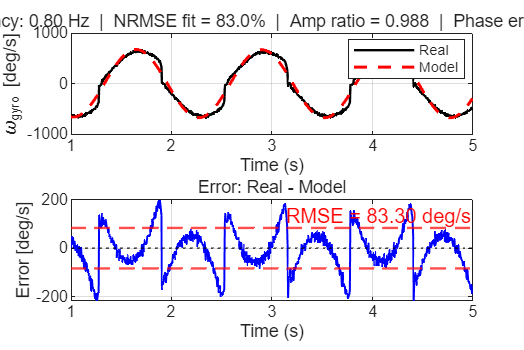

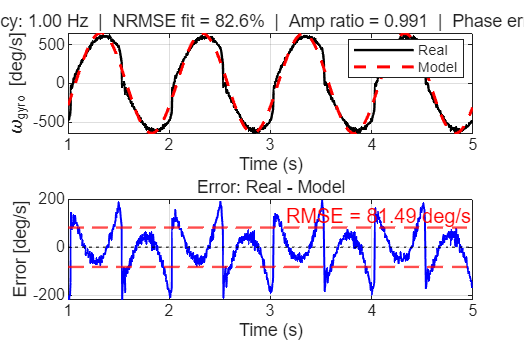

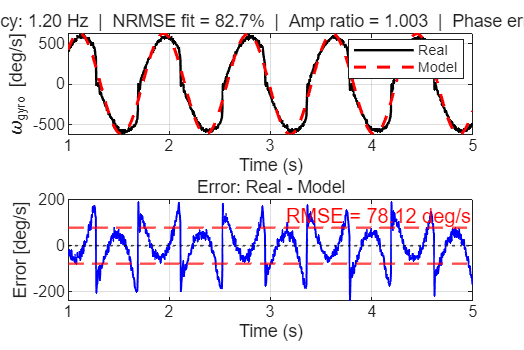

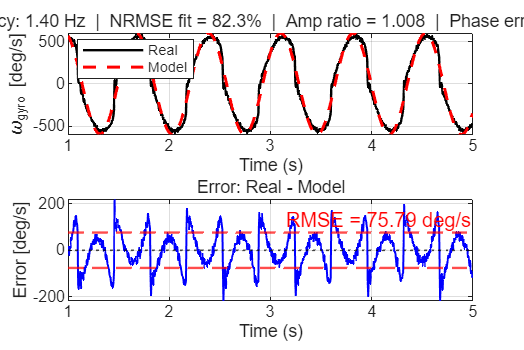


====== Validation Summary ======
Freq(Hz) RMSE       NRMSE fit%   Amp Ratio      Phase Err(deg)
------------------------------------------------------------
0.20     64.81      88.8         1.098          -0.6          
0.40     66.56      87.1         1.036          -0.5          
0.60     79.41      84.6         0.973          1.5           
0.80     83.30      83.0         0.988          2.0           
1.00     81.49      82.6         0.991          1.0           
1.20     78.12      82.7         1.003          0.5           
1.40     75.79      82.3         1.008          -1.2          
1.60     75.05      81.9         0.992          -1.9          
1.80     72.63      81.9         0.998          -3.2          
2.00     70.86      81.5         0.991          -3.5          


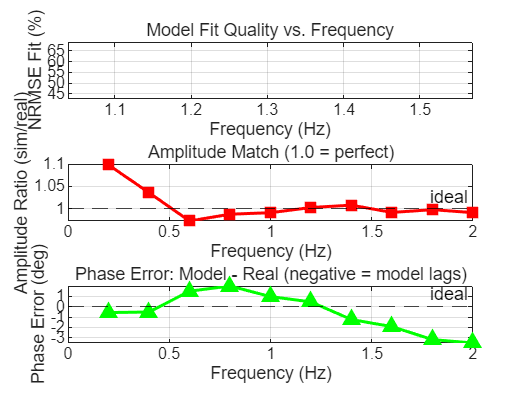

Trans_func_valid(path); 